% I = imread('Images/s1.JPG');
% x = [1046.5  2342.5 2762.5 2538.5 1842.5 726.5];
% y  = [1454.5 1370.5 2426.5 3238.5 3334.5 2270.5];
% BW = roipoly(I ,x,y);
% imshow(I)
% figure
% imresize(BW, [275 183]);
% imshow(BW);
% imwrite(BW, 's1_mask.jpg');

# Part 1 

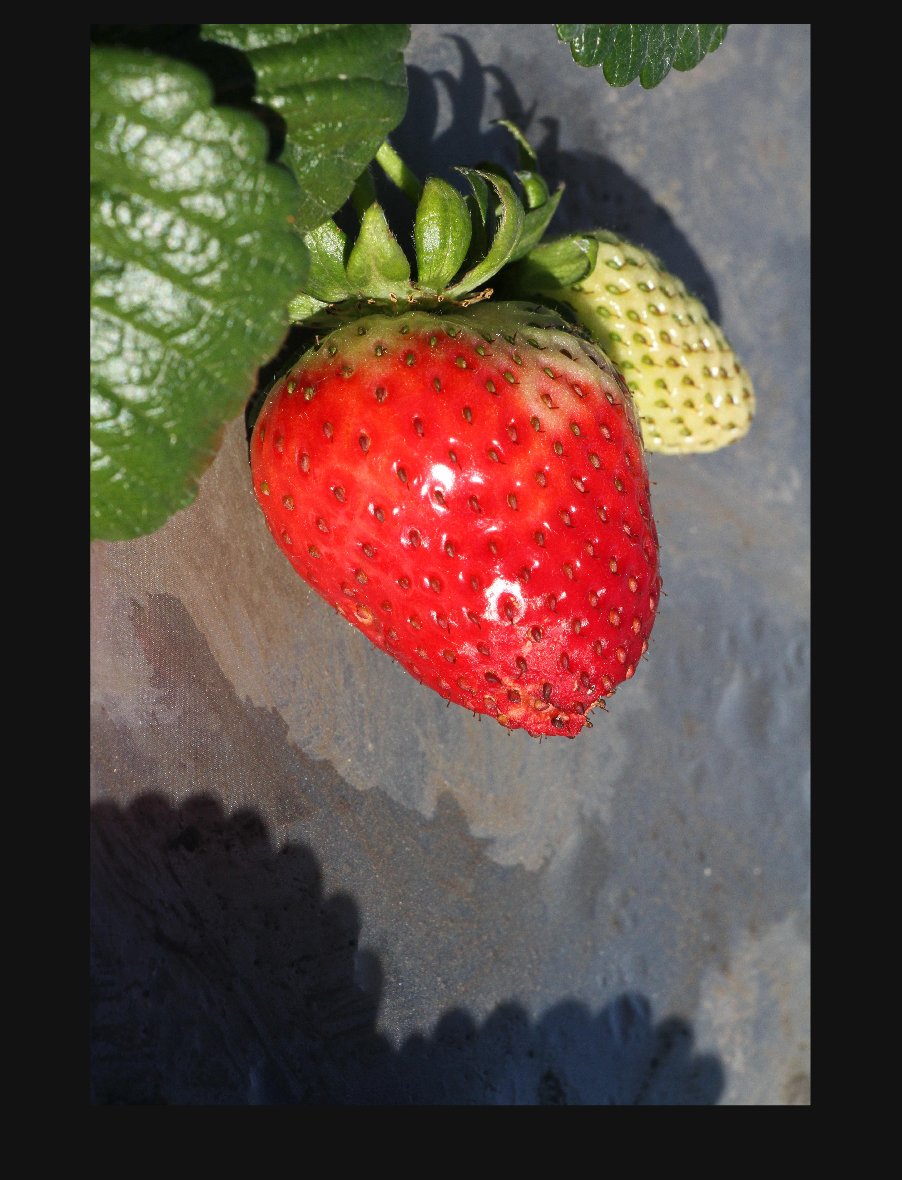

Error using resizeParseInputs
Expected input number 1, A, to be nonempty.

Error in matlab.images.internal.resize.resizeParseInputs>parsePreMethodArgs (line 113)
validateattributes(A, {'single', ...
^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in 

 for x = 1:20

    I = imread(sprintf('Images/s%d.JPG', x));
    BW = roipoly(I);
    imshow(I)
    figure
    imresize(BW, [275 183]);
    imshow(BW);
    imwrite(BW, sprintf('s%d_mask.mat', x));
end

% I = imread('Images/s1.JPG');
% I2 = imread('Images/s2.JPG');
% I = [I(:); I2(:)]
% imhist(I)
I = [];
I_straw = [];
I_no_straw = [];
for x = 1:20
    I_temp = imread(sprintf('Images/s%d.JPG', x));
    imresize(I_temp, [275 183]);
    mask = imread(sprintf('s%d_mask.JPG', x));
    I = [I(:); I_temp(:)];
    J = imerase(I_temp,mask);
    I_no_straw = [I_no_straw(:); J(:)];
end

Error using imerase (line 45)
Invalid argument at position 2. Window vector length must be 4.

imhist(I)
imhist(I_no_straw)